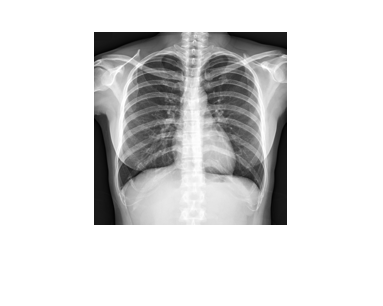

% Cargar imagen y darle tamano adecuado
f = imread('radiograph1.jpg');
f = double(f(:,:,1));
f = f/max(max(f));
f = imresize(f,0.15);
figure
imshow(f,[]);

Thresholding

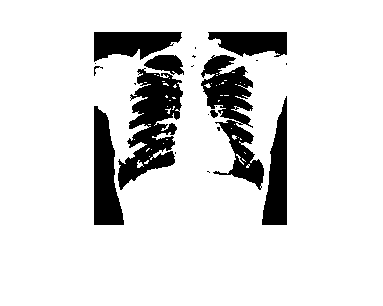

%Creacion de segmentos para tipos de tejido
seg1 = f > 0.5;
imshow(seg1,[]);

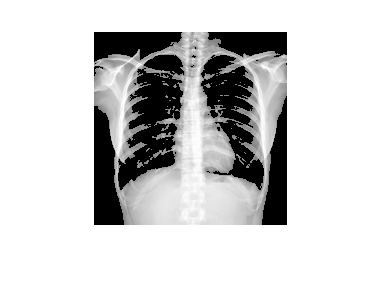

imshow(seg1.*f,[]);

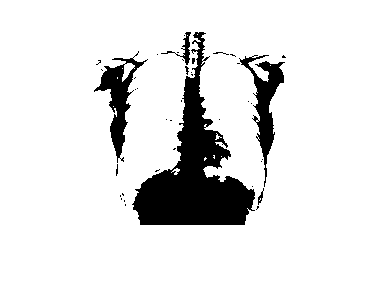


seg1 = f < 0.75;
imshow(seg1,[]);

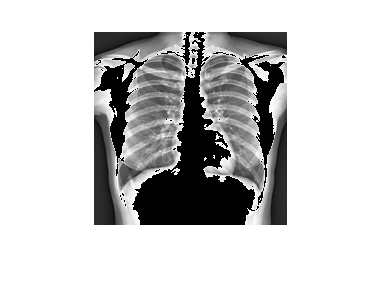

imshow(seg1.*f,[]);

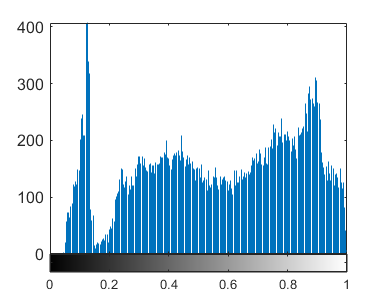


imhist(f)

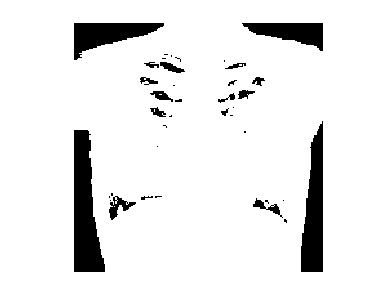


%Use a third threshold based on hist
seg1 = f > 0.25;
imshow(seg1,[]);

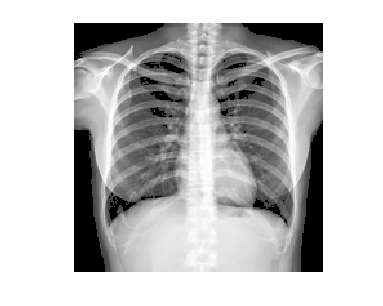

imshow(seg1.*f,[]);

Otsu method

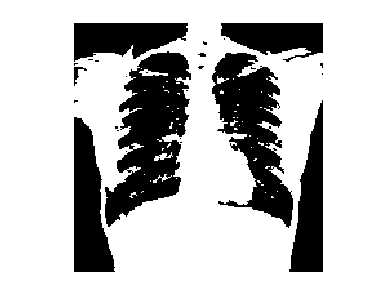

thr = graythresh(f);
seg1 = f > thr;
imshow(seg1,[]);

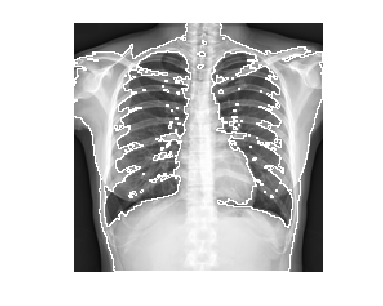

dxp = [0,1;-1,0];
dyp = [1,0;,0,-1];
edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same'));
imshow(f+edgemap,[0,1]);

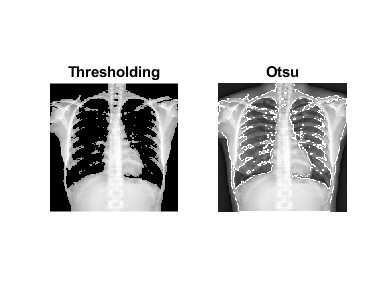


%Compare otsu provided threshold vs the one you selected in the prev step
figure(1)
subplot(1,2,1)
imshow(seg1.*f,[]);
title('Thresholding')

subplot(1,2,2)
imshow(f+edgemap,[0,1]);
title('Otsu')

Do u trust the otsu method?

Los errores en este metodo son mas dificil de comprender y observar

No tiene sentido biologicamente

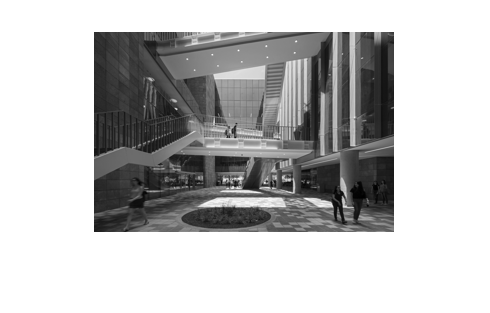

% Select your own imagen and compute this threshold
a = imread('PatioCentral.jpg');
a = double(a(:,:,1));
a = a/max(max(a));
a = imresize(a,0.15);
figure
imshow(a,[]);

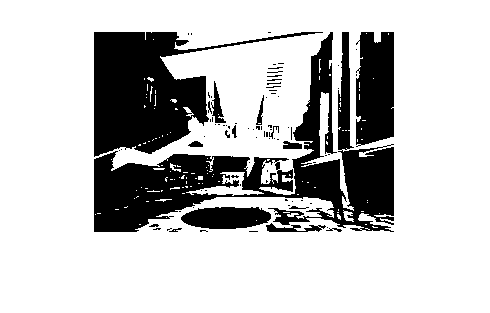


thr = graythresh(a);
segA = a > thr;
imshow(segA,[]);

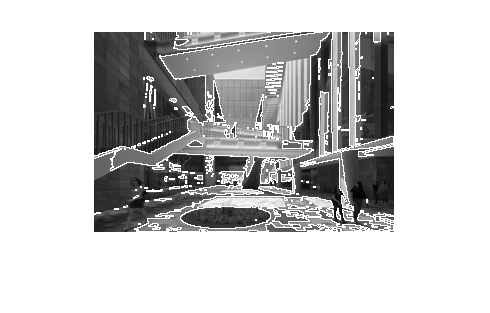

dxp = [0,1;-1,0];
dyp = [1,0;0,-1];
edgemap = abs(conv2(segA,dxp,'same'))+abs(conv2(segA,dyp,'same'));
imshow(a+edgemap,[0,1]);

Kmeans Seg

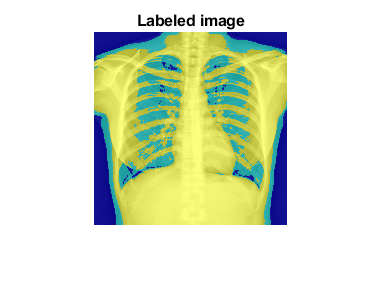

[L,centers] = imsegkmeans(int8(255*f),3);
B = labeloverlay(f,L);
[L1,centers1] = imsegkmeans(int8(255*f),5);
B1 = labeloverlay(f,L1);

figure
imshow(B)
title('Labeled image')

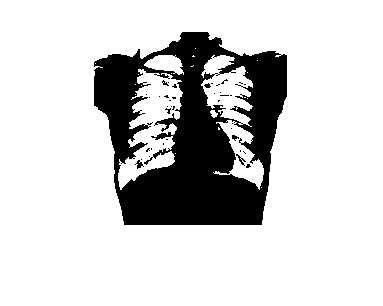

figure
imshow(int8(255*f) < centers(1),[])

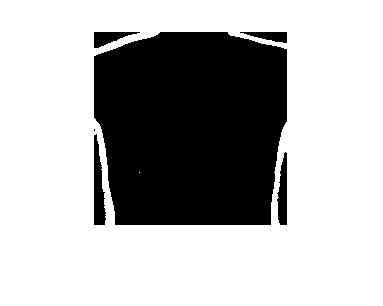

imshow(int8(255*f) < centers(2),[])

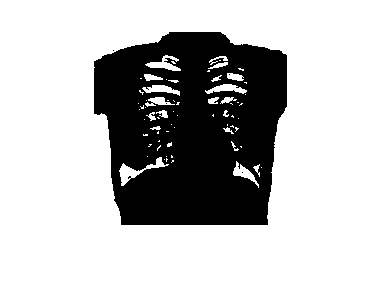

imshow(int8(255*f) < centers(3),[])

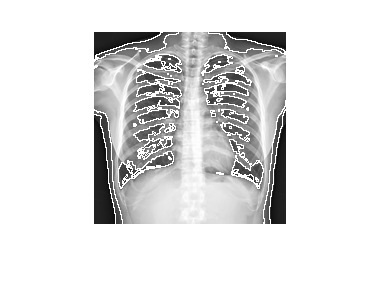

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);


% Do the same procedure but with five centers
figure
subplot(1,2,1)
imshow(B)
title ('Tres centros')
subplot(1,2,2)
imshow(B1)
title ('Cinco centros')


% Is the segmetation better?
% Por parte del analisis biologico el proceso con cinco centros para ser 
% mas preciso en la deteccion y display de los tipos de tejido, en este
% caso podemos ver con mayor facilidad el aire en los pulmones

Watershed

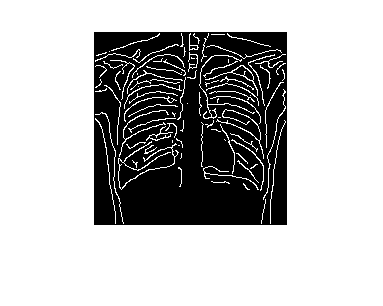

edgeC = edge(f,'Canny');
figure
imshow(edgeC,[])

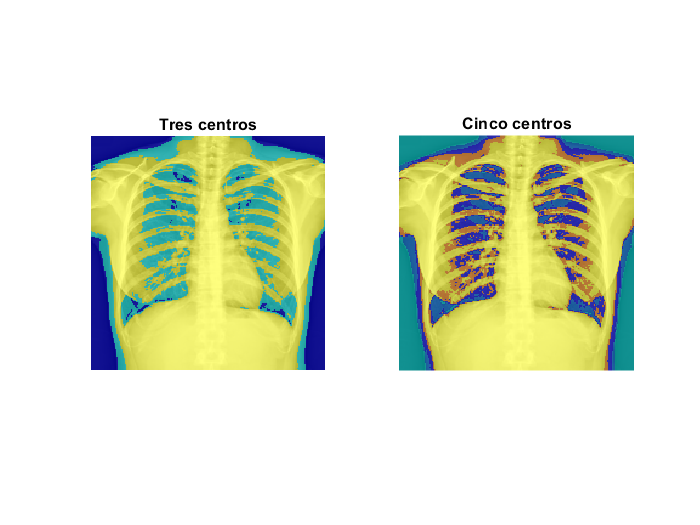

D = bwdist(edgeC);
imshow(D,[])

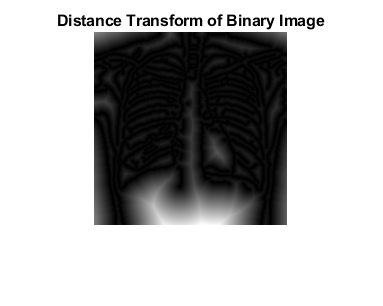

title('Distance Transform of Binary Image')

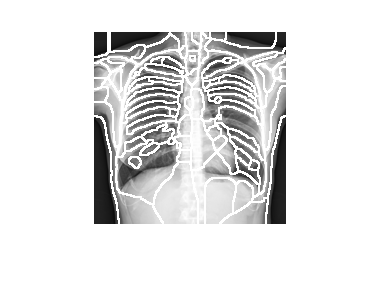

L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);


L(edgeC) = 0;

Display the resulting label matrix as an RGB image

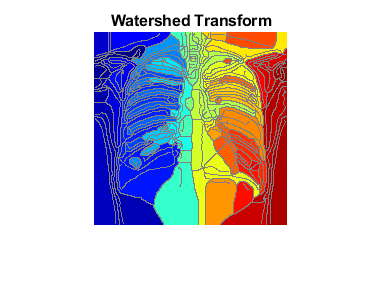

rgb = label2rgb(L,'jet',[.5 .5 .5]);
figure
imshow(rgb)
title('Watershed Transform')